cnc_params;
showplots = false;
w_max = -2*pi*500

w_max = -3.1416e+03

pol_d = 45;

eps = 0.01;
KF_poles = -2*[pol_d+eps pol_d-eps pol_d]

KF_poles =   -90.0200  -89.9800  -90.0000


% Obsv_poles =9.5*[-51  -50 -49 ]; % hat: theta omega torque
LQ_poles = -[pol_d+eps pol_d-eps];  % u: theta omega 




P0 = P_ext(1);
P1 = P_ext(2);

b21 = (k *r /Ra)/J_tilda;


A0 = [0 1 ; 
    0 -P0];
A1 = [0 1 ; 
    0 -P1];
B = [0 ; -b21];
C = [1 0];



M = B; % For Volt disturbance


G0ss = tf(ss(A0,B,C,0));
G1ss = tf(ss(A1,B,C,0));

## Simple KF

noise_v = 20/4016 * 1/sqrt(12); % LSB /sqrt(12)
noise_x =noise_v*b21;

disturbance_factor = 40;

Qkf_enl =  diag([noise_x noise_x disturbance_factor*noise_x]);


Qkf = Qkf_enl(1:2,1:2);
Rkf = 2*pi/4096 * 1/sqrt(12);
C_full_obs = eye(2);

% Feasibility Checks
Bq = sqrt(Qkf);

rank(ctrb(A0,Bq))==2

ans = logical
   1


rank(obsv(A0,C))==2

ans = logical
   1




% Calc
L0_kf = lqr(A0',C', Qkf, Rkf)' ;
A0_kf = A0 - L0_kf*C;
B0_kf = [B L0_kf];
sysKF0 = ss(A0_kf,B0_kf,C_full_obs,0);

L1_kf = lqr(A1',C', Qkf, Rkf)' ;
A1_kf = A1 - L1_kf*C;
B1_kf = [B L1_kf];
sysKF1 = ss(A1_kf,B0_kf,C_full_obs,0);


## Enlarged KF



C_full_obs_enl =  eye(3);

A0_enl = [A0 B; 0 0 0];
A1_enl = [A1 B; 0 0 0];
B_enl = [B; 0];
C_enl = [C 0];

L0_enl_kf = lqr(A0_enl',C_enl', Qkf_enl, Rkf)' ;
A0_enl_kf = A0_enl - L0_enl_kf*C_enl;
B0_enl_kf = [B_enl L0_enl_kf];
sysKF0_enl = ss(A0_enl_kf,B0_enl_kf,C_full_obs_enl,0);


L1_enl_kf = lqr(A1_enl',C_enl', Qkf_enl, Rkf)' ;
A1_enl_kf = A1_enl - L1_enl_kf*C_enl;
B1_enl_kf = [B_enl L1_enl_kf];
sysKF1_enl = ss(A1_enl_kf,B1_enl_kf,C_full_obs_enl,0);


% sysKF0_enl_d = c2d(sysKF0_enl,1/500);

%% LQR

Rlq = [1/20] % cost of input

Rlq = 0.0500


theta_max = deg2rad(40);
speed_max = 40;

Qlq = diag([ 1/theta_max 1/(speed_max*theta_max)  ]); % cost of states
Cq = sqrt(Qlq)

Cq =     1.1968         0
         0    0.1892


Nlq = [0 0]';

K0_lq = lqr(A0,B,Qlq, Rlq,Nlq) 

K0_lq =    -5.3524   -0.5166



K1_lq = lqr(A1,B,Qlq, Rlq,Nlq) 


## Loop Transfer Recovery

% from : https://ocw.mit.edu/courses/2-154-maneuvering-and-control-of-surface-and-underwater-vehicles-13-49-fall-2004/resources/lec21/
Q_ltr = C_full_obs'*C_full_obs

Q_ltr =      1     0
     0     1



rho = 1e-3;
R_ltr = rho

R_ltr = 1.0000e-03


K0_ltr = lqr(A0,B,Q_ltr, R_ltr,Nlq) 

K0_ltr =   -31.6228  -30.9171



K1_ltr = lqr(A1,B,Q_ltr, R_ltr,Nlq) 


K0_lq =   -31.6228  -30.9171


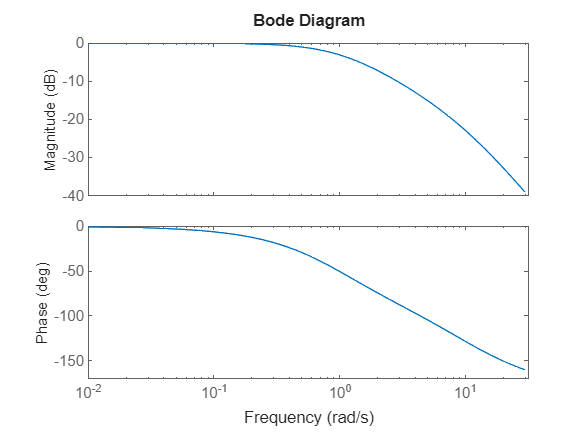

if showplots
A0_kf_bar = A0 - L0_kf*C - B*K0_lq;

R0_kf =  ss(A0_kf_bar,L0_kf,K0_lq,0);
GAMMA0_kf = ss(A0_kf_bar,B,-K0_lq,1);

T0_kf = feedback(R0_kf*G0ss,1,-1);
S0_kf = feedback(1,R0_kf*G0ss,-1);

% step(GAMMA0)
step(T0_kf)
% step(S0)
bode(T0_kf,{0,30})

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% A1_bar = A1o - L1o*C - B*K1pp;
% 
% R1 =  ss(A1_bar,L1o,K1pp,0);
% GAMMA1 = ss(A1_bar,B,-K1pp,1);
% 
% T1 = feedback(R1*G1ss,1,-1);
% S1 = feedback(1,R1*G1ss,-1);
% 
% % step(GAMMA1)
% step(T1)
% % step(S1)
% 
% bode(T1,{0,30})

end